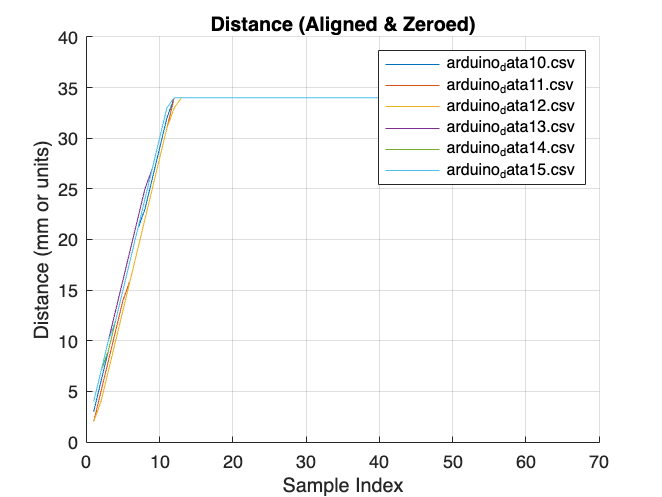

%% Synced & Zeroed Traction Test Plotter: Distance and Force

% Clear workspace and figures
clear;
close all;

%% Folder and file setup
dataFolder = 'sample3';
filePattern = fullfile(dataFolder, 'arduino_data*.csv');
csvFiles = dir(filePattern);

if isempty(csvFiles)
    error('No CSV files found in folder "%s" matching pattern "%s".', dataFolder, filePattern);
end

% Initialize storage
distanceData = {};
forceData = {};
fileLabels = {};

% Threshold to detect start of test
forceThreshold = 10000;  % adjust as needed to avoid noise

%% Load and process data
for i = 1:length(csvFiles)
    fullPath = fullfile(dataFolder, csvFiles(i).name);
    data = readmatrix(fullPath);
    
    if size(data, 2) < 2
        warning('File %s does not have at least two columns. Skipping...', csvFiles(i).name);
        continue;
    end
    
    distance = data(:, 1);
    force = data(:, 2);
    
    % Find index where force exceeds threshold
    startIdx = find(force > forceThreshold, 1, 'first');
    
    if isempty(startIdx)
        warning('No valid test start found in %s. Skipping...', csvFiles(i).name);
        continue;
    end
    
    % Trim and zero-align
    trimmedDistance = distance(startIdx:end);
    trimmedForce = force(startIdx:end);
    
    % Zero the distance (remove initial encoder offset)
    zeroedDistance = trimmedDistance - distance(1);
    
    % Store results
    distanceData{end+1} = zeroedDistance;
    forceData{end+1} = trimmedForce;
    fileLabels{end+1} = csvFiles(i).name;
end

%% Plot Distance vs. Sample Index
figure;
hold on;
for i = 1:length(distanceData)
    plot(distanceData{i}, 'DisplayName', fileLabels{i});
end
title('Distance (Aligned & Zeroed)');
xlabel('Sample Index');
ylabel('Distance (mm or units)');
legend('show');
grid on;

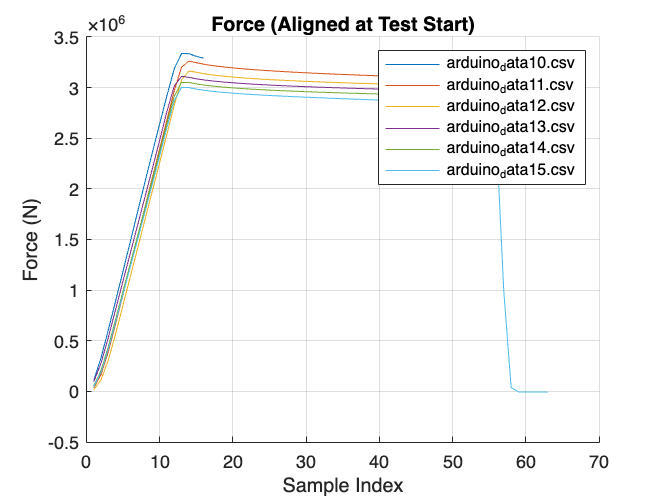


%% Plot Force vs. Sample Index
figure;
hold on;
for i = 1:length(forceData)
    plot(forceData{i}, 'DisplayName', fileLabels{i});
end
title('Force (Aligned at Test Start)');
xlabel('Sample Index');
ylabel('Force (N)');
legend('show');
grid on;

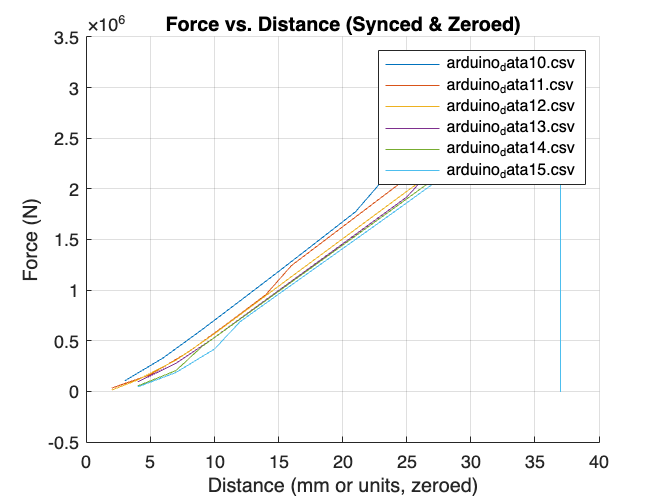


%% Plot Force vs. Distance (Main Output)
figure;
hold on;
for i = 1:length(forceData)
    plot(distanceData{i}, forceData{i}, 'DisplayName', fileLabels{i});
end
title('Force vs. Distance (Synced & Zeroed)');
xlabel('Distance (mm or units, zeroed)');
ylabel('Force (N)');
legend('show');
grid on;